# Explore Symbolic computing with MATLAB `- part 2`

In this script we're going to explore MATLAB's ability to do symbolic computing - so we'll be using MATLAB and the Symbolic toolbox.  

Specifically we'll look at some common calculus topics that science and engineering students are taught, ie: we'll look at using/applying the symbolic expressions and functions that we learnt about in PART 1 of this tutorial.  In this (part 2) tutorial we'll look at how to perform:

- Plotting symbolic functions

- Differentiation                 

- Integration 

- Laplace transforms

- ODEs

We'll also look at how to do some of these things **Numerically**:

- ODEs  with MATLAB

- ODEs with Simulink (why let the engineers have all the fun ??)                                           

and  ... don't forget the DOC

- the DOC                 

`15-Nov-2016 : Bradley Horton, bradley.horton@mathworks.com.au`                

## Plotting 2D functions :   $y=f\left(x\right)$

A function of the form *f(x)*, can be plot/visualized using the `fplot()` function:

syms X
y = 20 + X^2 - 10*(cos(2*pi*X) + 1 );

Now plot it using the `fplot()` function ... and put add some annotations:

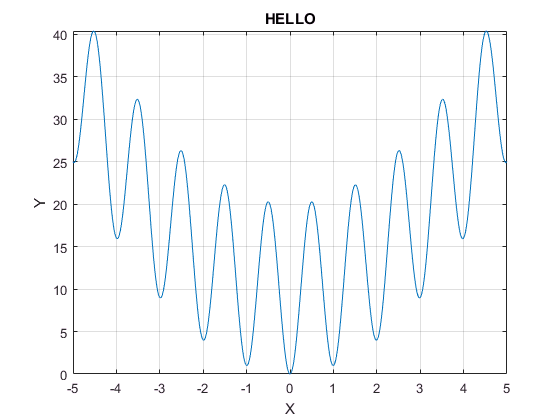

figure; 
        fplot(y, [-5 5]);

        title('HELLO')
        xlabel('X'); ylabel('Y'); grid('on')

## Plotting multiple 2D functions :   $f\left(x\right)$and $g\left(x\right)$

In this example, we'll plot 2 functions on the same axes.  The new concept here is the use of the `hold()` function which allows us to target the same axis for multiple plotting tasks.

*GOTCHA: if we didn't use the *`hold()`* function, our first plot would be deleted and we'd only see the last(most recent) plot.*

syms x

f(x) = 20 + 5*sin(2*pi*x);
g    = 2*x^2 -3*x + 5;

Create a figure window and plot *f(x)*

figure;
        fplot(f, [-3, 5], '-b'); 

Hold on to that plot :

hold('on');

and add the second plot of *g(x) *

fplot(g, [-3, 5], '-r'); 

Annotate the plot

grid('on'); xlabel('POSITION'); ylabel('VOLTS');

Add some Latex Markup for the title:

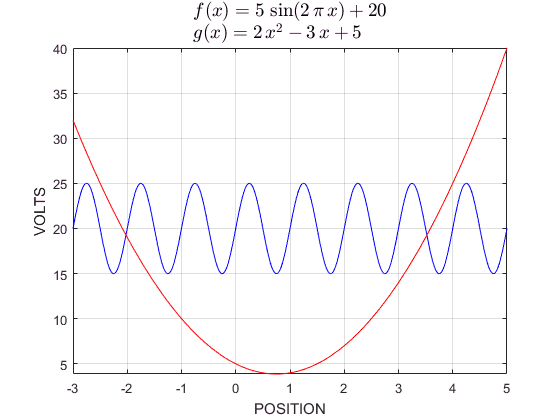

title_latex = {['$f(x)=', latex(f), '$'], ...
               ['$g(x)=', latex(g), '$'] };   
%title_latex = ['\fontsize{14}{0}$f(x)=', latex(f), '$'];
title(title_latex,'Interpreter','latex', 'FontSize', 14)

## Plotting 2D functions :   colors, thickness

And one more time, where you can see how to control some of the properties of the curve being plotted, eg: it's color and thickness.

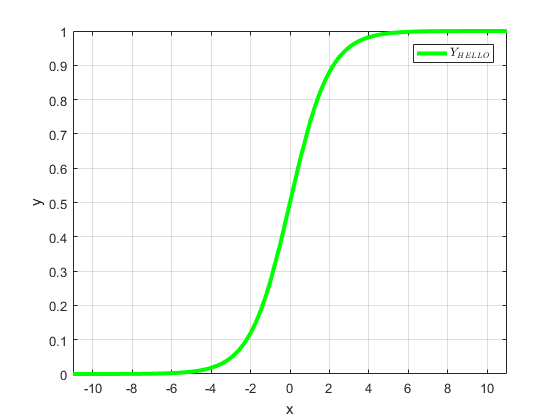

syms x
y = 1/(1 + exp(-x));

figure;
        fplot(y, [-11, 11], 'LineWidth', 3, 'Color', [0 1 0]);

        grid('on'); xlabel('x'); ylabel('y');
        legend({'$Y_{HELLO}$'}, 'Interpreter', 'latex')

## **Plotting 2D functions :   **$x\left(\theta \right),\text{ }\text{ }y\left(\theta \right)$

The `fplot()` function can also plot parametric curves:

syms theta

r = 10*sin(4*theta);  % say the radius of a point
x = r*cos(theta);
y = r*sin(theta);

and plot for $−\pi \text{ }\le \theta \le \pi$

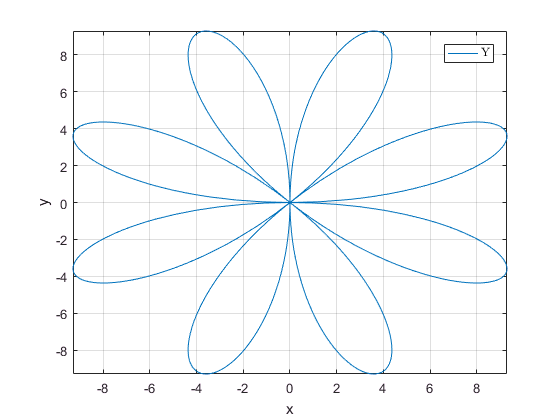

figure;
        fplot(x, y, [-pi, pi] );

        grid('on'); xlabel('x'); ylabel('y');
        legend({'Y'}, 'Interpreter', 'latex')

## Plotting 3D functions :   $z=f\left(x,y\right)$

To plot a surface, use the `fsurf()` function:

syms x y  

f = 3*(1-x)^2*exp(-(x^2)-(y+1)^2)...
   - 10*(x/5 - x^3 - y^5)*exp(-x^2-y^2)...
   - 1/3*exp(-(x+1)^2 - y^2);

Now plot it:

figure;
        h = fsurf(f,[-3 3]);

Annotate the plot

xlabel('x'); ylabel('y'); zlabel('z'); 
title_latex = ['$' latex(f) '$'];
title(title_latex,'Interpreter','latex','FontSize', 14)

Put a frame around the plot

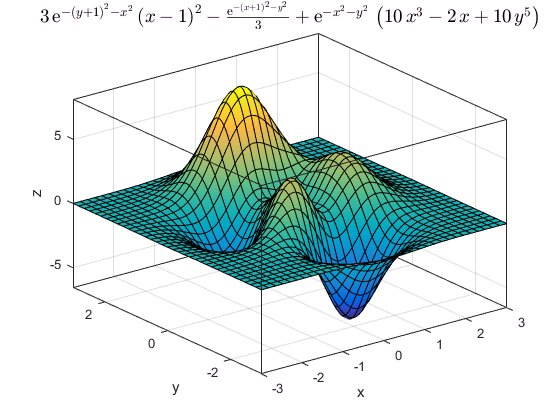

a = gca;
a.Box = 'on';
a.BoxStyle = 'full';

## **Plotting 3D functions :   **$x\left(s,t\right),\text{ }\text{ }y\left(s,t\right),\text{ }\text{ }z\left(s,t\right)$

The `fsurf()` function can also plot parametric surfaces.

syms s t
r = 2 + sin(7*s + 5*t);
x = r*cos(s)*sin(t);
y = r*sin(s)*sin(t);
z = r*cos(t);

Create the plot for:

- 
$$0<s<2\pi$$


- 
$$0<t<\pi$$


figure;
        fsurf(x, y, z, [0, 2*pi, 0, pi])

add a lighting model and alter view angles

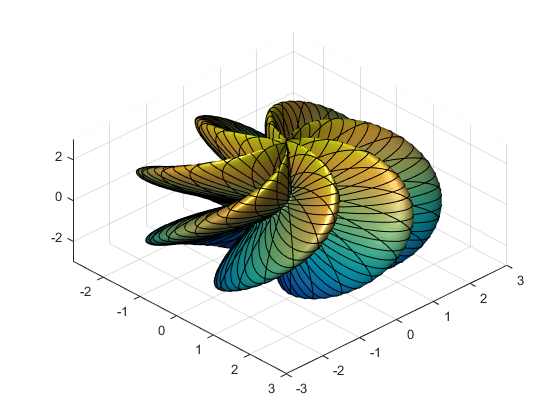

camlight
view(46,52)

## Implicit functions:  f(x,y)

To make a 2D plot of a function expressed in the form f(x,y), use the plotting function called `fimplicit()`:

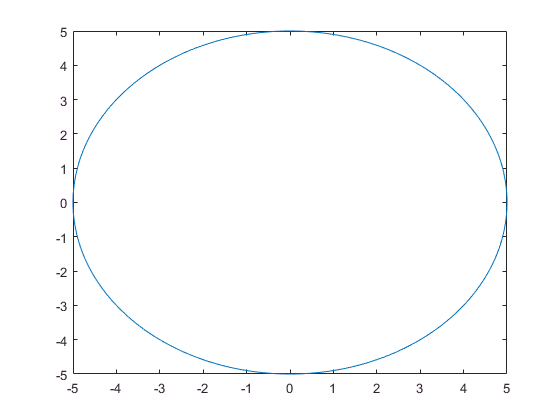

syms x y
f(x,y) = x^2 + y^2 - 25;

figure;  fimplicit(f)

## Implicit functions:  f(x,y,z)

To make a 3D plot of a function expressed in the form f(x,y,z), use the plotting function called `fimplicit3()`:

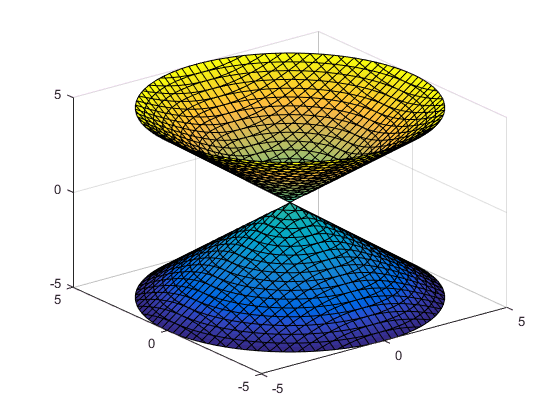

syms x y z
f(x,y,z) = x^2 + y^2 - z^2;

figure;  fimplicit3(f)

## Finding Analytical solutions:

**a.) In****tegration**:  Let's do this:  $f(t) = \int e^{-3t}sin(5t) dt$

syms t
dfa_dt = exp(-3*t)*sin(5*t); % the integrand

fa     = int( dfa_dt, t)     % <------ and the INDEFINITE integral is 

$$fa = -\frac{{\mathrm{e}}^{-3\,t}\,\left(5\,\cos\left(5\,t\right)+3\,\sin\left(5\,t\right)\right)}{34}$$

**b.) Differentiation**:  Let's do this: $f(t)=cos(2t)e^{5t} \longrightarrow  $so what is $\frac{df}{dt}$ ?

fb     = cos(2*t)*exp(5*t);

dfb_dt = diff(fb, t)        % <------ and the derivative is 

$$dfb\_dt = 5\,\cos\left(2\,t\right)\,{\mathrm{e}}^{5\,t}-2\,\sin\left(2\,t\right)\,{\mathrm{e}}^{5\,t}$$

**c.) La****place transforms**:  Let's do this: $f(t)=cos(2t)e^{5t} \longrightarrow  $so what is $F(s) = \mathcal{L}\{f(t)\}$ ?

syms s
my_ft = cos(2*t)*exp(5*t);

my_Fs = laplace(my_ft, t, s)

$$my\_Fs = \frac{s-5}{{\left(s-5\right)}^{2}+4}$$

And let's do the inverse too:

fc = ilaplace(my_Fs, s, t)

$$fc = \cos\left(2\,t\right)\,{\mathrm{e}}^{5\,t}$$

**ODEs**:  solve this $\thinspace\ddot{x}(t) + 4 \thinspace.\thinspace\dot{x}(t) + 100 \thinspace.\thinspace x(t) = 200.u(t-5)$

% define some SYMBOLIC variables 
syms t x(t)

% our excitation force
f  = 200*heaviside(t-5);       

Construct the ODE:     $\thinspace\ddot{x}(t) + 4 \thinspace.\thinspace\dot{x}(t) + 100 \thinspace.\thinspace x(t) = 200.u(t-5)$  

with   $\matrix{\bullet  \quad x(0) = 5 \cr
\bullet \quad \dot{x}(0) = 0}$

% construct the SYMBOLIC 2nd order ODE 
EQ = 1*diff(x,2) + 4*diff(x,1) + 100*x == f

$$EQ(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+4\,\frac{\partial }{\partial t}x\left(t\right)+100\,x\left(t\right)=200\,\mathrm{heaviside}\left(t-5\right)$$

Now find the analytical solution:

% now find the analytical solution applying our IC's
dx(t) = diff( x(t), t);

x     = dsolve( EQ,   x(0)==5,    ...
                     dx(0)==0,    ...
                    'IgnoreAnalyticConstraints',false);
             
x  = simplify(x)             

$$x = \begin{array}{l} 2\,\mathrm{heaviside}\left(t-5\right)+5\,{\mathrm{e}}^{-2\,t}\,\cos\left(4\,\sqrt{6}\,t\right)+\frac{5\,\sqrt{6}\,{\mathrm{e}}^{-2\,t}\,\sin\left(4\,\sqrt{6}\,t\right)}{12}-2\,\mathrm{heaviside}\left(t-5\right)\,{\mathrm{e}}^{-2\,t}\,{\mathrm{e}}^{10}\,\cos\left(\sigma_{1}\right)-\frac{\sqrt{6}\,\mathrm{heaviside}\left(t-5\right)\,{\mathrm{e}}^{-2\,t}\,{\mathrm{e}}^{10}\,\sin\left(\sigma_{1}\right)}{6}\\ \mathrm{where}\\ \sigma_{1}=4\,\sqrt{6}\,t-20\,\sqrt{6} \end{array}$$

             
% compute the velocity (because we can)
v = diff(x,t)

$$v = \begin{array}{l} 2\,\delta (t-5)-\frac{125\,\sqrt{6}\,{\mathrm{e}}^{-2\,t}\,\sin\left(4\,\sqrt{6}\,t\right)}{6}-2\,\delta (t-5)\,{\mathrm{e}}^{-2\,t}\,{\mathrm{e}}^{10}\,\cos\left(\sigma_{1}\right)-\frac{\sqrt{6}\,\delta (t-5)\,{\mathrm{e}}^{-2\,t}\,{\mathrm{e}}^{10}\,\sin\left(\sigma_{1}\right)}{6}+\frac{25\,\sqrt{6}\,\mathrm{heaviside}\left(t-5\right)\,{\mathrm{e}}^{-2\,t}\,{\mathrm{e}}^{10}\,\sin\left(\sigma_{1}\right)}{3}\\ \mathrm{where}\\ \sigma_{1}=4\,\sqrt{6}\,t-20\,\sqrt{6} \end{array}$$

Plot the solution 

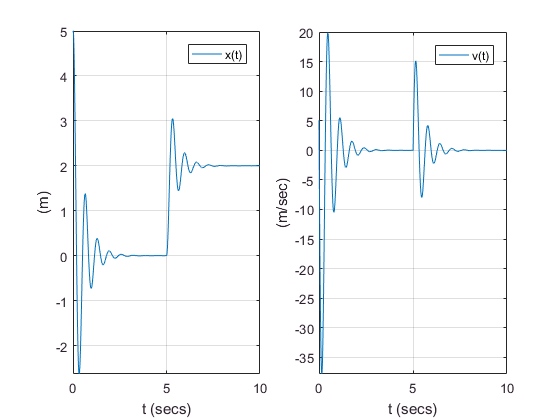

figure;

subplot(1,2,1)
                fplot( x, [-0.01, 10]);
                       xlabel('t (secs)'); 
                       ylabel('(m)'); 
                       grid('on'); legend('x(t)')
subplot(1,2,2)
               fplot( v, [-0.01, 10]);
                      xlabel('t (secs)'); 
                      ylabel('(m/sec)'); 
                      grid('on');   legend('v(t)')

*FYI: a symbolic expression can be converted into LaTex code using the *`latex()`* function.  You could then copy and paste this into your own latex files OR into a latex viewer(eg: *[***QuickLaTex.com***](http://quicklatex.com/)*) in your web browser(remember to include the  $ $ )*

latex(x)                      

ans = 2\, \mathop{\mathrm{heaviside}}\nolimits\!\left(t - 5\right) + 5\, \mathrm{e}^{- 2\, t}\, \cos\!\left(4\, \sqrt{6}\, t\right) + \frac{5\, \sqrt{6}\, \mathrm{e}^{- 2\, t}\, \sin\!\left(4\, \sqrt{6}\, t\right)}{12} - 2\, \mathop{\mathrm{heaviside}}\nolimits\!\left(t - 5\right)\, \mathrm{e}^{- 2\, t}\, \mathrm{e}^{10}\, \cos\!\left(4\, \sqrt{6}\, t - 20\, \sqrt{6}\right) - \frac{\sqrt{6}\, \mathop{\mathrm{heaviside}}\nolimits\!\left(t - 5\right)\, \mathrm{e}^{- 2\, t}\, \mathrm{e}^{10}\, \sin\!\left(4\, \sqrt{6}\, t - 20\, \sqrt{6}\right)}{6}

## Finding NUMERICAL solutions to ODEs:

In the previous example we found the symbolic solution to the ODE:

 $\thinspace\ddot{x}(t) + 4 \thinspace.\thinspace\dot{x}(t) + 100 \thinspace.\thinspace x(t) = 200.u(t-5)$  with   $\matrix{x(0) = 5 \cr
\dot{x}(0) = 0}$

Sometimes we won't be able to find a nice analytical solution, and in these cases we'll want to NUMERICALLY solve our system of ODEs.  A common workflow that leverages MATLAB's ability to do both symbolic and numeric computing is this one:

- use symbolic computing to create your system of ODEs

- automatically convert these ODEs into a sequense of 1st order ODEs

- automatically convert these ODEs into a MATLAB function

- invoke one of MATLAB's ODE solvers

**Re****call our symbolic equation:**

EQ

$$EQ(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+4\,\frac{\partial }{\partial t}x\left(t\right)+100\,x\left(t\right)=200\,\mathrm{heaviside}\left(t-5\right)$$

Convert this into a collection of 1st order ODEs - we could certainly do this manually, but there's a nice function in the Symbolic toolbox called `odeToVectorField()` that will do it automatically.  Note that the relationship between the outputs is:

- $\text{ }V_i$  =  $\frac{d}{dt}Y_i$

[V_der_of_Y, Y] = odeToVectorField(EQ)

$$V\_der\_of\_Y = \left(\begin{array}{c} Y_{2}\\ 200\,\mathrm{heaviside}\left(t-5\right)-100\,Y_{1}-4\,Y_{2} \end{array}\right)$$

$$Y = \left(\begin{array}{c} x\\ \mathrm{Dx} \end{array}\right)$$

Note how our "state vector"  **Y** is made up of:

- 
$$x(t)$$


- 
$$\dot{x}(t)$$


Next we're going to convert this collection of 1st order ODEs into a MATLAB function file (ie: a *.m file)  - we're doing this because this is the form that we will be able to use with MATLAB's numeric ODE solvers.  The function `matlabFunction()` will automatically convert a symbolic expression into a MATLAB function and/or file:

matlabFunction(V_der_of_Y, ...
               'File' , 'bh_auto_gen_ODEsys', ...
               'vars',  {'t','Y'})

ans =     @bh_auto_gen_ODEsys


Define a function needed by the numeric ODE solvers, ie:  $\dot{y} = f(t,y)$

MY_SYSTEM_tY = @(t,Y) bh_auto_gen_ODEsys(t, Y )

MY_SYSTEM_tY =     @(t,Y)bh_auto_gen_ODEsys(t,Y)


Define your INITIAL conditions

init_x    = 5;
init_xdot = 0;

y_init    = [ init_x ;
              init_xdot   ;  ];

Specify some solver settings:

% Define some ODE solver settings
t_span     = [0 10];
my_options = odeset('RelTol', 1e-7, 'AbsTol', 1e-7);

Now invoke the `ode45()` solver

%[T,Y] = solver(odefun,   tspan,  y0,     options)
[T,Y]  = ode45(MY_SYSTEM_tY, t_span, y_init, my_options);

## Plot the NUMERIC solution:

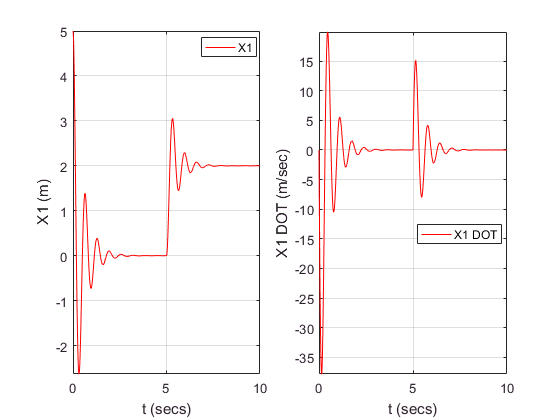

X1_dot = Y(:,2); 
X1     = Y(:,1);  

figure;
subplot(1,2,1);
   plot(T,X1,'-r');      xlabel('t (secs)'); ylabel('X1 (m)'); grid('on'); axis('tight');
                         legend('X1', 'Location', 'best');
   %----------------------------------------------------------------------- 
subplot(1,2,2);
   plot(T,X1_dot,'-r');  
                         xlabel('t (secs)'); ylabel('X1 DOT (m/sec)'); grid('on'); axis('tight');
                         legend('X1 DOT', 'Location', 'best');

**Another way of describing an ODE:**

MATLAB is very good at representing and solving ODEs.  But there is something even "cooler" !  Have you seen Simulink before? - it's a graphical block diagram languge for modelling dynamic systems.  The "graphical" nature of the language makes it very useful for representing feedback systems(eg: control systems, signal processing).  A spring mass damper ODE would look like this in Simulink:

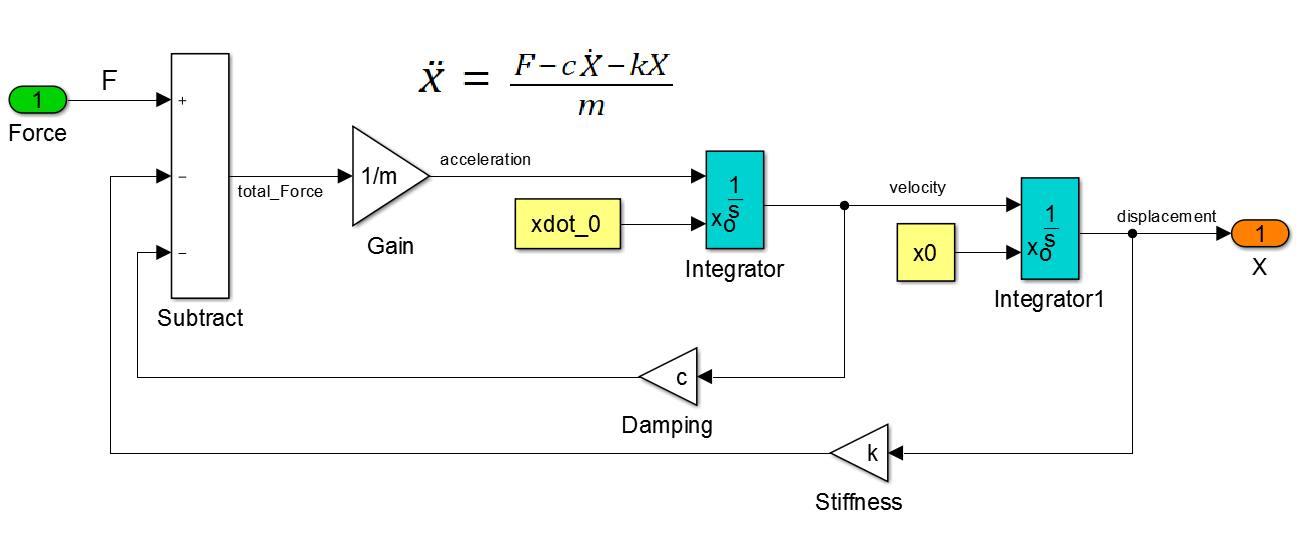

If you'd like to look at a Simulink model, try this:

% open_system('bh_1dof_hello')  

## The DOC

Look for this   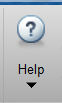 and click on it often !

The help browser lets you search using "plain english" keywords. You can search for:

- functions

- examples

- tutorials

Try this as an experiment: